%页码：P133
%作者；暴富
%时间：2024-08-1
%项目：控制协议和观测器协议中加权的重要性

clc
clear

%%系统初始化
A = [0,1,0;0,0,1;-0.2,0.2,1.1];
B = [0;0;1];
C = [0,0,1];

G = diag([30,0,0,0,30]);
E = [0 1 1 1 0;...
     1 0 1 1 0;...
     1 1 0 0 1;...
     0 0 1 0 1;...
     0 1 0 1 0];
D = diag(sum(E,2));
L = D -E;
varGamma  = (eye(5)+D+G)\(L+G);
varGamma_eig = eig(varGamma);

eig_LG = eig(L+G);
c0_org = (max(real(eig_LG))+min(real(eig_LG)))/2;
r0_org = max(abs(eig_LG - c0_org));

%Riccati设计
Q = diag([10 10 10]);  % 修改Q 可以得出不同的 r_obs
R = 0;
[F,P] = dlqr(A',C',Q,R); % 计算出控制增益F P125
% 计算r_obs
r_obs = (max(svd(inv(sqrtm(Q'))*A*P*C'*inv(C*P*C')*C*P*A'*inv(sqrtm(Q)))))^(-0.5);

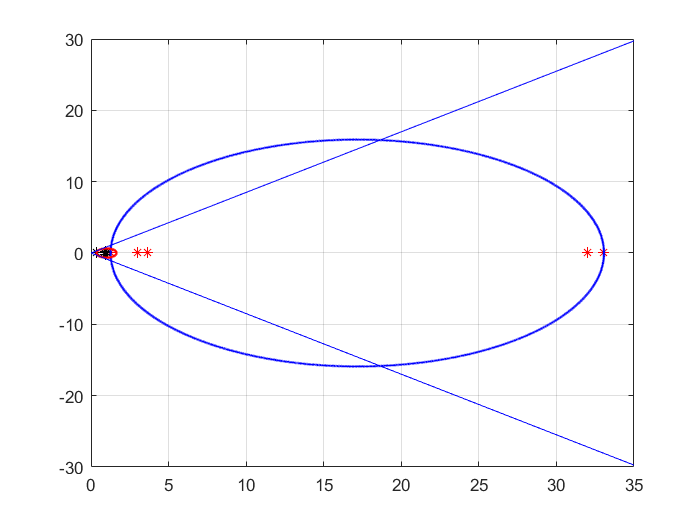

%作图
figure
%绘制无权重图的特征根
plot(real(eig_LG),imag(eig_LG),'r*')%表示实部和虚部
hold on
grid on

% 绘制有权重图的特征根
plot(real(varGamma_eig),imag(varGamma_eig),'k*') 

%绘制无权重特征值分布圆
theta = linspace(0,2*pi,1000);
LG_cir = c0_org + r0_org*exp(1j*theta);
plot(real(LG_cir),imag(LG_cir),'b.','MarkerSize',3)

% 绘制观测器收敛域图
r_obs_cir = 1 + r_obs*exp(1j*theta); 
plot(real(r_obs_cir),imag(r_obs_cir),'r.','MarkerSize',3);
% 绘制圆的切线
t = 0:0.5:35; 
L_cir_up = tan(asin(r_obs))*t;
L_cir_down = -tan(asin(r_obs))*t;
plot(t,L_cir_up,'b-',t,L_cir_down,'b-')
grid on 

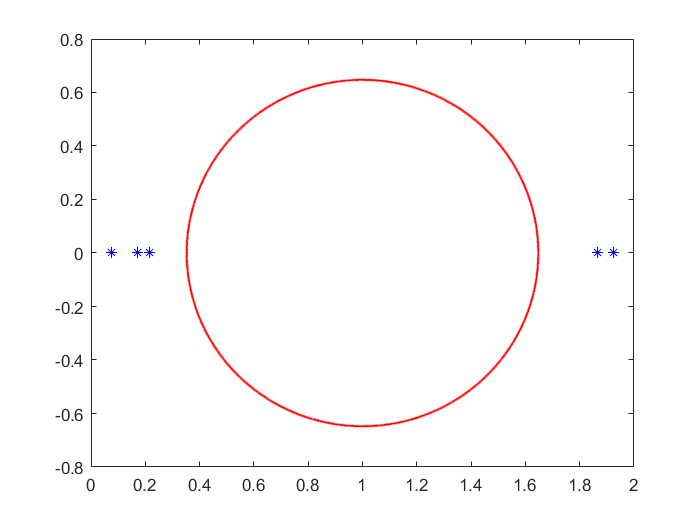

%验证乘c看是否落在同步区域
c = 1/c0_org;
figure
%乘c后的特征值
plot(real(eig_LG*c),imag(eig_LG*c),'b*')
hold on
% 绘制观测器收敛域图
r_obs_cir = 1 + r_obs*exp(1j*theta); 
plot(real(r_obs_cir),imag(r_obs_cir),'r.','MarkerSize',3);

### %这里为位似方便，这里将c0，变换到1，即乘以1/c0

## %%乘c后的特征值，不会落在同步区域

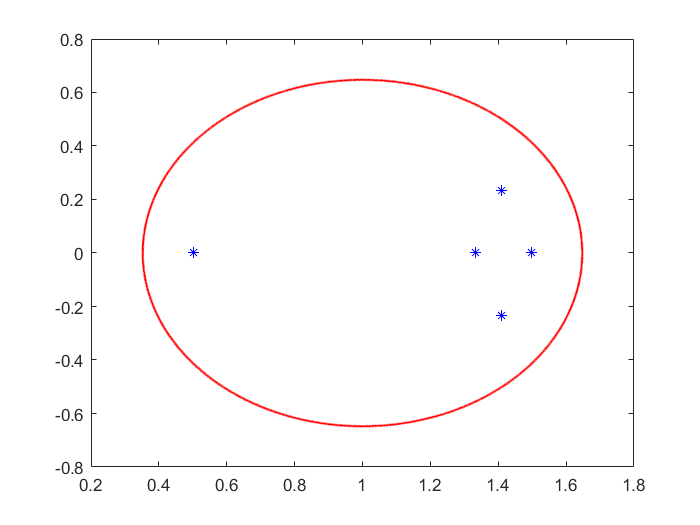

%看有权重的特征值是否落在同步区域
%加权后的特征值圆
c0 = (max(real(varGamma_eig))+min(real(varGamma_eig)))/2;
r0 = max(abs(varGamma_eig - c0));
c1 = 1/c0;
figure
%乘c后的特征值
plot(real(varGamma_eig*c1),imag(varGamma_eig*c1),'b*')
hold on
% 绘制观测器收敛域图
r_obs_cir = 1 + r_obs*exp(1j*theta); 
plot(real(r_obs_cir),imag(r_obs_cir),'r.','MarkerSize',3);